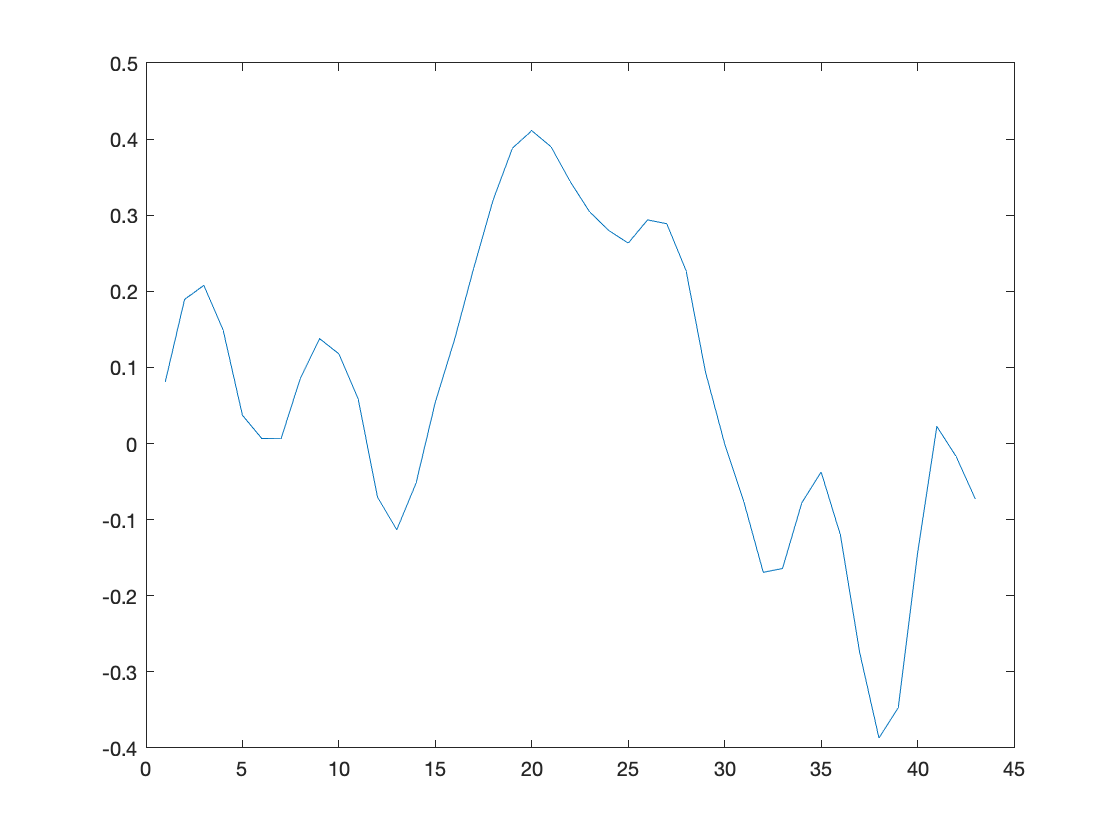

clc
clear all 

%%BAR DIMENSIONS
%Length
L = 1;
%Width
b = 0.037;
%height
height = 0.01;
%Cross-Sectional Area
A = b*height;
%Young's Modulus
E = 2.13 * 10^10;
%Density
p = 1015;
%Moment of Inertia
I = (b * height^3)/12;

Kappa = sqrt((E*I)/(p*A));

%Sampling Rate and other constants
Fs = 48000;
k = 1/Fs;
h = sqrt(2*Kappa*k);
N = floor(L/h);
h = L/N;
MU = (Kappa*k)/(h*h);

%%Update Vectors
uNext = zeros(N+1,1);

u = zeros(N+1,1);
u(3:9) = hann(7);

uPrev = u;

out = zeros(length(u),1);

range = (3:N-1);

boundaryCondition = 'f'; %%should be "s" or "f"

for n = 1:Fs
    
    uNext(range) =  ((2 - 6*MU*MU) * u(range)) + (4*MU*MU * (u(range+1) + u(range-1))) - (MU*MU * (u(range+2) + u(range-2))) - uPrev(range);
 
    %Add Boundary Conditions
    if boundaryCondition == 's' || boundaryCondition == 'f'
        uNext(2) = ((2 - 5*MU*MU) * u(2)) + ((4*MU*MU) * (u(3) + u(1))) - ((MU*MU) * u(4)) - uPrev(2);
        uNext(N) = ((2 - 5*MU*MU) * u(N)) + ((4*MU*MU) * (u(N+1) + u(N-1))) - ((MU*MU) * u(N-2)) - uPrev(N);
    end
    
    if boundaryCondition == 'f'
        uNext(1) = ((2 - 6*MU*MU) * u(1)) - ((2*MU*MU) * (u(3) - 2*u(2))) - uPrev(1);   
        uNext(N+1) = ((2 - 6*MU*MU) * u(N+1)) - ((2*MU*MU) * (u(N-1) - 2*u(N))) - uPrev(N+1);  
    end
    
%     uNext(10) = 0;
%     uNext(30) = 0;
    
  out(n) = u(7);
    plot(u);
    drawnow;
    
    
    uPrev = u;
    u = uNext;
end


%soundsc(out,Fs);
